# GFM-WT Control Parameter Stability-Domain Analysis

Builds stability maps for the control parameters that may influence drivetrain torsion and the remaining non-target unstable modes: h/mp, k_pdc/k_idc, k_pq/k_iq and K_damp. The operating point is fixed at the baseline power-flow condition since only controller parameters are varied in this study.

close all
clear
clc

## Load baseline parameters and GFM models

this_dir = fileparts(mfilename('fullpath'));
if isempty(this_dir)
    this_dir = pwd;
end
cd(this_dir);
addpath(genpath('D:\apps\matlab\R2024b\bin\matpower8.0'));

run("Parameters.m");
this_dir = pwd; % Parameters.m clears workspace variables.
base_params = load("Parameters.mat");
mpopt = mpoption('verbose', 0, 'out.all', 0);
base_params = add_operating_point(base_params, mpopt);

gfm_file = load("Unified_WT_PMSG_VSG.mat");
ad_file = load("Unified_WT_PMSG_VSG_Damping.mat");
gfm = gfm_file.Unified_GFMI;
ad = ad_file.Unified_GFMI;

result_dir = fullfile(this_dir, 'Control_Parameter_Scan_Results');
if ~exist(result_dir, 'dir')
    mkdir(result_dir);
end

## Compile fast numeric A-matrix functions

gfm_names = {'h', 'mp', 'k_pdc', 'k_idc', 'k_pq', 'k_iq'};
ad_names = {'h', 'mp', 'k_pdc', 'k_idc', 'k_pq', 'k_iq', 'K_damp'};
gfm_default = get_values(base_params, gfm_names);
ad_default = get_values(base_params, ad_names);

fprintf('Compiling control-parameter A-matrix functions...\n');

Compiling control-parameter A-matrix functions...


gfm_A = compile_A(gfm.sym_A, base_params, gfm_names);
ad_A = compile_A(ad.sym_A, base_params, ad_names);

A_gfm_base = evaluate_A(gfm_A, gfm_default);
A_ad_base = evaluate_A(ad_A, ad_default);
baseline = [make_metric_row("GFM-MWT", "Baseline", NaN, NaN, A_gfm_base, gfm.X_stac); ...
            make_metric_row("GFM-MWT+AD", "Baseline", NaN, NaN, A_ad_base, ad.X_stac)];
writetable(baseline, fullfile(result_dir, 'baseline_control_parameter_metrics.csv'));
participation = [top_participation("GFM-MWT", "Dominant", A_gfm_base, gfm.X_stac); ...
                 top_participation("GFM-MWT", "Torsional", A_gfm_base, gfm.X_stac); ...
                 top_participation("GFM-MWT+AD", "Dominant", A_ad_base, ad.X_stac); ...
                 top_participation("GFM-MWT+AD", "Torsional", A_ad_base, ad.X_stac)];
writetable(participation, fullfile(result_dir, 'baseline_mode_participation_top10.csv'));
fprintf('\nBaseline metrics for control-parameter screening\n');


Baseline metrics for control-parameter screening


disp(baseline);

       Model           Scan       XValue    YValue     MaxReal       Sigma      FrequencyHz    DampingRatio    Stable
    ____________    __________    ______    ______    _________    _________    ___________    ____________    ______

    "GFM-MWT"       "Baseline"     NaN       NaN      0.0050661    -0.090009      1.9973        0.0071723      false 
    "GFM-MWT+AD"    "Baseline"     NaN       NaN      0.0050947     -0.19496       1.986         0.015622      false 



fprintf('\nDominant and torsional baseline modal participation\n');


Dominant and torsional baseline modal participation


disp(participation);

       Model           Mode          Sigma      FrequencyHz    Rank      State       Participation
    ____________    ___________    _________    ___________    ____    __________    _____________

    "GFM-MWT"       "Dominant"     0.0050661           0         1     "omega_t"         0.88889  
    "GFM-MWT"       "Dominant"     0.0050661           0         2     "omega_g"         0.11111  
    "GFM-MWT"       "Dominant"     0.0050661           0         3     "theta_tw"     1.3036e-06  
    "GFM-MWT"       "Dominant"     0.0050661           0         4     "v_dc"         1.6338e-08  
    "GFM-MWT"       "Dominant"     0.0050661           0         5     "gamma_dc"     1.6337e-08  
    "GFM-MWT"       "Dominant"     0.0050661           0         6     "gamma_mq"     4.9618e-14  
    "GFM-MWT"       "Dominant"     0.0050661           0         7     "i_m_q"        4.3589e-17  
    "GFM-MWT"       "Dominant"     0.0050661           0         8     "delta"        6.9206e-19  
    "GFM-

## Paired parameter stability maps


Scanning VSG inertia and droop: h / mp


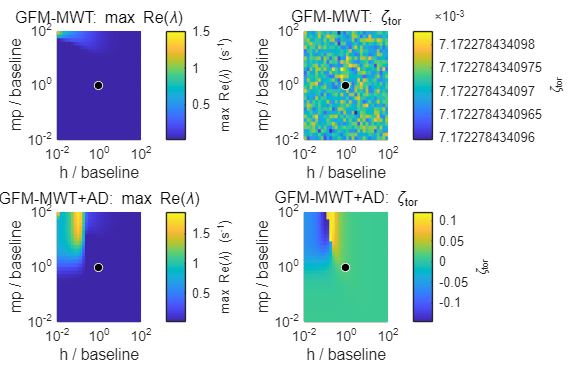


Scanning MSC DC-link voltage loop: k_pdc / k_idc


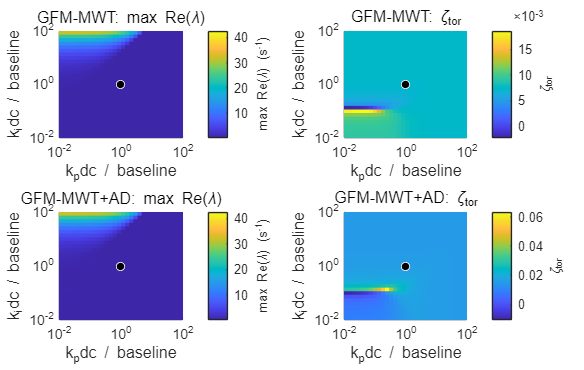


Scanning GFM reactive-power loop: k_pq / k_iq


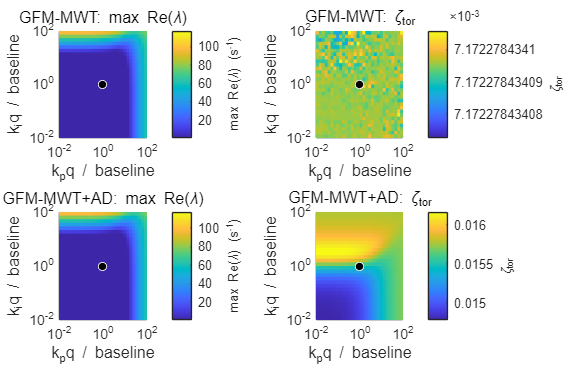

pair_scale = logspace(-2, 2, 31);
pair_defs = struct( ...
    'name', {"h_mp", "dvc", "rpc"}, ...
    'label', {"VSG inertia and droop", "MSC DC-link voltage loop", "GFM reactive-power loop"}, ...
    'x_name', {"h", "k_pdc", "k_pq"}, ...
    'y_name', {"mp", "k_idc", "k_iq"}, ...
    'gfm_idx', {[1 2], [3 4], [5 6]}, ...
    'ad_idx', {[1 2], [3 4], [5 6]});

pair_results = table();
summary = table();
for s = 1:numel(pair_defs)
    def = pair_defs(s);
    fprintf('\nScanning %s: %s / %s\n', def.label, def.x_name, def.y_name);

    [rows_gfm, maps_gfm] = run_pair_scan("GFM-MWT", def.name, gfm_A, gfm_default, ...
        def.gfm_idx, pair_scale, def.x_name, def.y_name, gfm.X_stac);
    [rows_ad, maps_ad] = run_pair_scan("GFM-MWT+AD", def.name, ad_A, ad_default, ...
        def.ad_idx, pair_scale, def.x_name, def.y_name, ad.X_stac);
    pair_results = [pair_results; rows_gfm; rows_ad]; %#ok<AGROW>
    summary = [summary; summarize_scan(rows_gfm); summarize_scan(rows_ad)]; %#ok<AGROW>

    plot_pair_maps(def, pair_scale, maps_gfm, maps_ad, result_dir);
end

writetable(pair_results, fullfile(result_dir, 'paired_parameter_scan_results.csv'));

## APCAD gain sweep

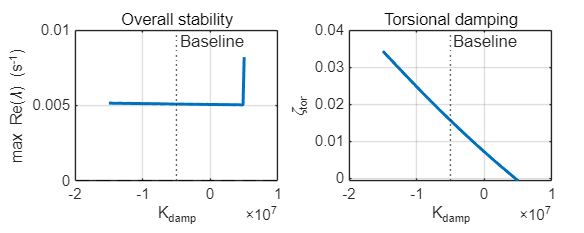

gain_values = linspace(-1.5e7, 5e6, 121);
kdamp_results = run_gain_scan(ad_A, ad_default, gain_values, ad.X_stac);
writetable(kdamp_results, fullfile(result_dir, 'kdamp_scan_results.csv'));
summary = [summary; summarize_scan(kdamp_results)]; %#ok<AGROW>
plot_gain_scan(kdamp_results, base_params.K_damp, result_dir);

## Write screening summary and MATLAB data package

writetable(summary, fullfile(result_dir, 'parameter_scan_summary.csv'));
save(fullfile(result_dir, 'control_parameter_scan_results.mat'), ...
    'baseline', 'participation', 'pair_defs', 'pair_scale', 'pair_results', 'kdamp_results', 'summary');

fprintf('\nControl-parameter scan summary\n');


Control-parameter scan summary


disp(summary);

       Model          Scan      Points    StablePoints    MinMaxReal    MaxMaxReal    MinDampingRatio    MaxDampingRatio    RecommendedXValue    RecommendedYValue    RecommendedMaxReal    RecommendedDampingRatio                RecommendationBasis            
    ____________    ________    ______    ____________    __________    __________    _______________    _______________    _________________    _________________    __________________    _______________________    ___________________________________________

    "GFM-MWT"       "h_mp"       961           0          0.0050661        1.5056         0.0071723         0.0071723               37268           1.1555e-06            0.0050661                0.0071723           "No stable point; minimum MaxReal reported"
    "GFM-MWT+AD"    "h_mp"       961           0          0.0050931        1.8621          -0.14839           0.11985               50661           1.5708e-08            0.0050931                0.0072459           "No sta

fprintf('\nResults written to:\n%s\n', result_dir);


Results written to:
D:\博士工作\论文工作\（1）小信号模型\Modularized-Small-Signal-Modeling-of-Grid-Forming-Inverters-main\EigenAnalysis\Control_Parameter_Scan_Results


## Supporting functions

function params = add_operating_point(params, mpopt)
mpc = SMIB_PowerFlow(params.rg, params.lg);
pf = runpf(mpc, mpopt);
assert(pf.success == 1, 'Power flow failed at the baseline control-parameter condition.');

angle_rad = deg2rad(pf.bus(1, 9));
voltage_mag = pf.bus(1, 8);
vc_phasor = voltage_mag * params.V_LL / sqrt(3) * exp(1j * angle_rad);
vg_phasor = params.V_LL / sqrt(3);
zt = params.rf2 + params.rg + 1j * 2*pi*params.f_base*(params.lf2 + params.lg);
z2 = params.rf2 + 1j * 2*pi*params.f_base*params.lf2;
i2_phasor = (vc_phasor - vg_phasor) / zt;
vpcc_phasor = (vc_phasor - i2_phasor*z2) * sqrt(2);

params.delta0 = angle_rad;
params.Vpcc_D0 = real(vpcc_phasor);
params.Vpcc_Q0 = imag(vpcc_phasor);
vc_dq0 = vc_phasor * exp(-1j*angle_rad) * sqrt(2);
params.Vc_d0 = real(vc_dq0);
params.Vc_q0 = imag(vc_dq0);
i2_dq0 = i2_phasor * exp(-1j*angle_rad) * sqrt(2);
params.i2_d0 = real(i2_dq0);
params.i2_q0 = imag(i2_dq0);
end

function values = get_values(params, names)
values = zeros(1, numel(names));
for k = 1:numel(names)
    values(k) = params.(names{k});
end
end

function A_fun = compile_A(sym_A, params, variable_names)
fixed_names = setdiff(fieldnames(params), variable_names, 'stable');
fixed_values = cell(size(fixed_names));
for k = 1:numel(fixed_names)
    fixed_values{k} = params.(fixed_names{k});
end
reduced_A = subs(sym_A, fixed_names, fixed_values);
remaining = string(arrayfun(@char, symvar(reduced_A), 'UniformOutput', false));
unexpected = setdiff(remaining, string(variable_names));
assert(isempty(unexpected), 'A matrix contains unsubstituted variables: %s', join(unexpected, ', '));
variables = cell(size(variable_names));
for k = 1:numel(variable_names)
    variables{k} = sym(variable_names{k});
end
A_fun = matlabFunction(reduced_A, 'Vars', variables);
end

function A = evaluate_A(A_fun, values)
args = num2cell(values);
A = double(A_fun(args{:}));
end

function [rows, maps] = run_pair_scan(model, scan_name, A_fun, defaults, indexes, scales, x_name, y_name, state_vector)
n = numel(scales);
max_real = zeros(n, n);
sigma = zeros(n, n);
frequency = zeros(n, n);
damping = zeros(n, n);
for iy = 1:n
    for ix = 1:n
        values = defaults;
        values(indexes(1)) = defaults(indexes(1)) * scales(ix);
        values(indexes(2)) = defaults(indexes(2)) * scales(iy);
        metric = torsion_metric(evaluate_A(A_fun, values), state_vector);
        max_real(iy, ix) = metric.MaxReal;
        sigma(iy, ix) = metric.Sigma;
        frequency(iy, ix) = metric.FrequencyHz;
        damping(iy, ix) = metric.DampingRatio;
    end
end
[x_factor, y_factor] = meshgrid(scales, scales);
rows = table(repmat(string(model), n*n, 1), repmat(string(scan_name), n*n, 1), ...
    repmat(string(x_name), n*n, 1), repmat(string(y_name), n*n, 1), ...
    x_factor(:), y_factor(:), defaults(indexes(1))*x_factor(:), defaults(indexes(2))*y_factor(:), ...
    max_real(:), sigma(:), frequency(:), damping(:), max_real(:) < 0, ...
    'VariableNames', {'Model', 'Scan', 'XParameter', 'YParameter', 'XFactor', 'YFactor', ...
    'XValue', 'YValue', 'MaxReal', 'Sigma', 'FrequencyHz', 'DampingRatio', 'Stable'});
maps = struct('MaxReal', max_real, 'DampingRatio', damping);
end

function rows = run_gain_scan(A_fun, defaults, gains, state_vector)
n = numel(gains);
max_real = zeros(n, 1);
sigma = zeros(n, 1);
frequency = zeros(n, 1);
damping = zeros(n, 1);
for k = 1:n
    values = defaults;
    values(7) = gains(k);
    metric = torsion_metric(evaluate_A(A_fun, values), state_vector);
    max_real(k) = metric.MaxReal;
    sigma(k) = metric.Sigma;
    frequency(k) = metric.FrequencyHz;
    damping(k) = metric.DampingRatio;
end
rows = table(repmat("GFM-MWT+AD", n, 1), repmat("K_damp", n, 1), gains(:), ...
    max_real, sigma, frequency, damping, max_real < 0, ...
    'VariableNames', {'Model', 'Scan', 'Value', 'MaxReal', 'Sigma', 'FrequencyHz', 'DampingRatio', 'Stable'});
end

function metric = torsion_metric(A, state_vector)
[V, D, W] = eig(A);
poles = diag(D);
max_real = max(real(poles));
lam = poles(select_torsion_mode(V, W, poles, state_vector));
metric = struct('MaxReal', max_real, 'Sigma', real(lam), ...
    'FrequencyHz', abs(imag(lam))/(2*pi), 'DampingRatio', -real(lam)/abs(lam));
end

function mode_index = select_torsion_mode(V, W, poles, state_vector)
positive_modes = find(imag(poles) > 1e-6);
frequencies = abs(imag(poles(positive_modes))) / (2*pi);
states = string(arrayfun(@char, state_vector, 'UniformOutput', false));
mechanical_states = ismember(states(:), ["omega_t", "omega_g", "theta_tw"]);
candidate_modes = positive_modes(frequencies > 0.2 & frequencies < 8);
if isempty(candidate_modes)
    [~, nearest] = min(abs(frequencies - 2));
    candidate_modes = positive_modes(nearest);
end
score = zeros(size(candidate_modes));
for k = 1:numel(candidate_modes)
    pf = abs(V(:, candidate_modes(k)) .* conj(W(:, candidate_modes(k))));
    score(k) = sum(pf(mechanical_states)) / sum(pf);
end
[~, best] = max(score);
mode_index = candidate_modes(best);
end

function rows = top_participation(model, mode_label, A, state_vector)
[V, D, W] = eig(A);
poles = diag(D);
if mode_label == "Dominant"
    [~, mode_index] = max(real(poles));
else
    mode_index = select_torsion_mode(V, W, poles, state_vector);
end
pf = abs(V(:, mode_index) .* conj(W(:, mode_index)));
pf = pf / sum(pf);
states = string(arrayfun(@char, state_vector, 'UniformOutput', false));
states = states(:);
[sorted_pf, order] = sort(pf, 'descend');
n = min(10, numel(order));
order = order(1:n);
rows = table(repmat(string(model), n, 1), repmat(string(mode_label), n, 1), ...
    repmat(real(poles(mode_index)), n, 1), repmat(abs(imag(poles(mode_index)))/(2*pi), n, 1), ...
    (1:n).', states(order), sorted_pf(1:n), ...
    'VariableNames', {'Model', 'Mode', 'Sigma', 'FrequencyHz', 'Rank', 'State', 'Participation'});
end

function row = make_metric_row(model, scan_name, x_value, y_value, A, state_vector)
metric = torsion_metric(A, state_vector);
row = table(string(model), string(scan_name), x_value, y_value, metric.MaxReal, metric.Sigma, ...
    metric.FrequencyHz, metric.DampingRatio, metric.MaxReal < 0, ...
    'VariableNames', {'Model', 'Scan', 'XValue', 'YValue', 'MaxReal', 'Sigma', 'FrequencyHz', 'DampingRatio', 'Stable'});
end

function summary = summarize_scan(rows)
stable_rows = rows(rows.Stable, :);
if isempty(stable_rows)
    [best_max_real, best_idx] = min(rows.MaxReal);
    best = rows(best_idx, :);
    best_zeta = best.DampingRatio;
    stable_count = 0;
    status = "No stable point; minimum MaxReal reported";
else
    [best_zeta, best_idx] = max(stable_rows.DampingRatio);
    best = stable_rows(best_idx, :);
    best_max_real = best.MaxReal;
    stable_count = height(stable_rows);
    status = "Stable point with maximum torsional damping";
end
if ismember('XFactor', rows.Properties.VariableNames)
    x_value = best.XValue;
    y_value = best.YValue;
else
    x_value = best.Value;
    y_value = NaN;
end
summary = table(best.Model, best.Scan, height(rows), stable_count, min(rows.MaxReal), max(rows.MaxReal), ...
    min(rows.DampingRatio), max(rows.DampingRatio), x_value, y_value, best_max_real, best_zeta, status, ...
    'VariableNames', {'Model', 'Scan', 'Points', 'StablePoints', 'MinMaxReal', 'MaxMaxReal', ...
    'MinDampingRatio', 'MaxDampingRatio', 'RecommendedXValue', 'RecommendedYValue', ...
    'RecommendedMaxReal', 'RecommendedDampingRatio', 'RecommendationBasis'});
end

function plot_pair_maps(def, scales, gfm_maps, ad_maps, result_dir)
fig = figure('Color', 'w', 'Position', [60 60 1200 760]);
tiledlayout(2, 2, 'Padding', 'compact', 'TileSpacing', 'compact');
draw_map(nexttile, scales, gfm_maps.MaxReal, def, "GFM-MWT: max Re(\lambda)", 'max Re(\lambda) (s^{-1})', true);
draw_map(nexttile, scales, gfm_maps.DampingRatio, def, "GFM-MWT: \zeta_{tor}", '\zeta_{tor}', false);
draw_map(nexttile, scales, ad_maps.MaxReal, def, "GFM-MWT+AD: max Re(\lambda)", 'max Re(\lambda) (s^{-1})', true);
draw_map(nexttile, scales, ad_maps.DampingRatio, def, "GFM-MWT+AD: \zeta_{tor}", '\zeta_{tor}', false);
exportgraphics(fig, fullfile(result_dir, sprintf('%s_stability_maps.png', def.name)), 'Resolution', 300);
end

function draw_map(ax, scales, values, def, plot_title, color_label, show_boundary)
surf(ax, scales, scales, values, 'EdgeColor', 'none');
view(ax, 2);
set(ax, 'XScale', 'log', 'YScale', 'log');
ax.Toolbar.Visible = 'off';
hold(ax, 'on');
if show_boundary && min(values, [], 'all') <= 0 && max(values, [], 'all') >= 0
    contour(ax, scales, scales, values, [0 0], 'k-', 'LineWidth', 1.2);
end
plot3(ax, 1, 1, max(values, [], 'all') + eps, 'wo', 'MarkerFaceColor', 'k', 'MarkerSize', 5);
xlabel(ax, sprintf('%s / baseline', def.x_name));
ylabel(ax, sprintf('%s / baseline', def.y_name));
title(ax, plot_title);
cb = colorbar(ax);
cb.Label.String = color_label;
grid(ax, 'on');
end

function plot_gain_scan(rows, base_gain, result_dir)
fig = figure('Color', 'w', 'Position', [80 80 1080 430]);
tiledlayout(1, 2, 'Padding', 'compact', 'TileSpacing', 'compact');
ax1 = nexttile;
ax1.Toolbar.Visible = 'off';
plot(ax1, rows.Value, rows.MaxReal, 'LineWidth', 1.8);
hold(ax1, 'on');
yline(ax1, 0, 'k--', 'HandleVisibility', 'off');
xline(ax1, base_gain, ':', 'Baseline', 'LabelOrientation', 'horizontal');
grid(ax1, 'on');
xlabel(ax1, 'K_{damp}');
ylabel(ax1, 'max Re(\lambda) (s^{-1})');
title(ax1, 'Overall stability');

ax2 = nexttile;
ax2.Toolbar.Visible = 'off';
plot(ax2, rows.Value, rows.DampingRatio, 'LineWidth', 1.8);
hold(ax2, 'on');
xline(ax2, base_gain, ':', 'Baseline', 'LabelOrientation', 'horizontal');
grid(ax2, 'on');
xlabel(ax2, 'K_{damp}');
ylabel(ax2, '\zeta_{tor}');
title(ax2, 'Torsional damping');
exportgraphics(fig, fullfile(result_dir, 'kdamp_scan.png'), 'Resolution', 300);
end